# K-means Clustering

Gaussian Mixtures: Sometimes a single class has various sub-classes. 

(E.g. the Letter 'A' is a single class but can be hand-written various ways, each individual way is a sub-class.)

% k-means clustering on heightweight dataset.
tbl = readtable("heightWeight.csv")

tbl = 210×3 table
    Var1    Var2    Var3
    ____    ____    ____

     1       67     125 
     2       68     140 
     2       67     142 
     2       60     110 
     2       64      97 
     2       61     106 
     1       79     210 
     2       61     110 
     1       71     150 
     2       66     145 
     2       60     113 
     1       71     175 
     1       72     145 
     2       55     110 
     2       64     112 
     2       65     135 


% Features on 2nd and 3rd Column
heightWeightLabelled = table2array(tbl);
heightWeight1 = heightWeightLabelled(heightWeightLabelled(:,1) == 1,:);
heightWeight2 = heightWeightLabelled(heightWeightLabelled(:,1) == 2,:);
heightWeight = heightWeightLabelled(:, 2:3);

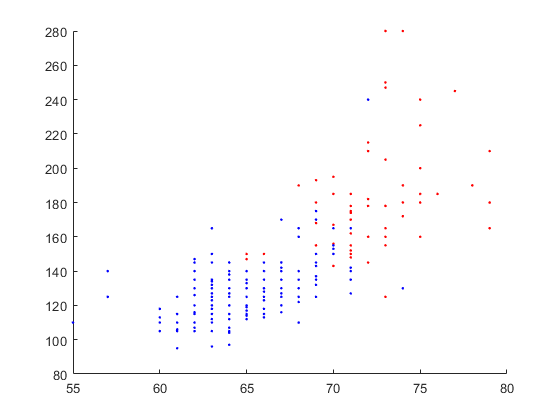

% Plot the initial dataset with actual labels
figure
hold on
plot(heightWeight1(:,2),heightWeight1(:,3), 'r.'); %Class 1
plot(heightWeight2(:,2),heightWeight2(:,3), 'b.'); %Class 2
hold off

[rows, d] = size(heightWeight);

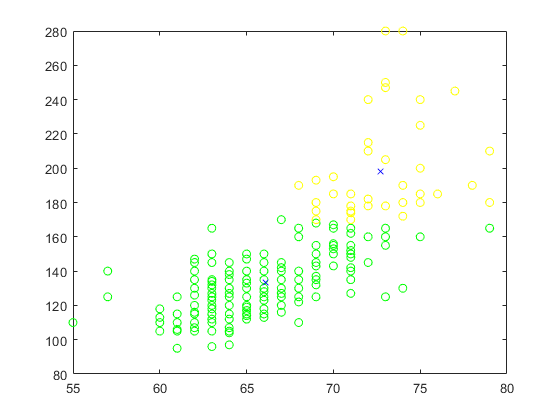

% [new_x, centers] = kMeans_test(100, 2, heightWeight);
maximum_iterations = 15;
centers = heightWeight(randsample(rows,2), :);
for i=1:maximum_iterations
    label_x = zeros(rows,1);
    
    for j=1:rows
            distances = zeros(2,1);
            % M returns the smallest value in each column.
            % I returns the row-index in which the smallest value appears.
            distances(1,:) = sum(((centers(1,:) - heightWeight(j,:)).^2));
            distances(2,:) = sum(((centers(2,:) - heightWeight(j,:)).^2));
      
            [na, I] = min(distances);
            label_x(j)=I;
    end
    for l=1:2
            centers(l,:)=mean(heightWeight(label_x==l, :), 1); %new means for cluster 1 to cluster k
    end
    new_x = label_x;
end


plot(heightWeight(new_x==1,1), heightWeight(new_x==1,2), 'go', ...
     heightWeight(new_x==2,1), heightWeight(new_x==2,2), 'yo', ...
     centers(:,1), centers(:,2), 'bx')